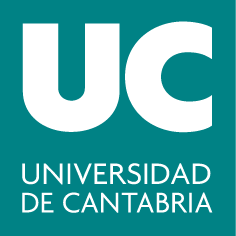

***Grado de Tecnologías de Telecomunicación***

**G282: Álgebra y Geometría**

# **Prácticas 1 y 2: Introducción a MATLAB**

*Dpto. Matemática Aplicada y Ciencias de la Computación*

**Objetivos**

- Familiarizarse con el entorno MATLAB

- Crear vectores y matrices

- Calcular determinantes e inversas

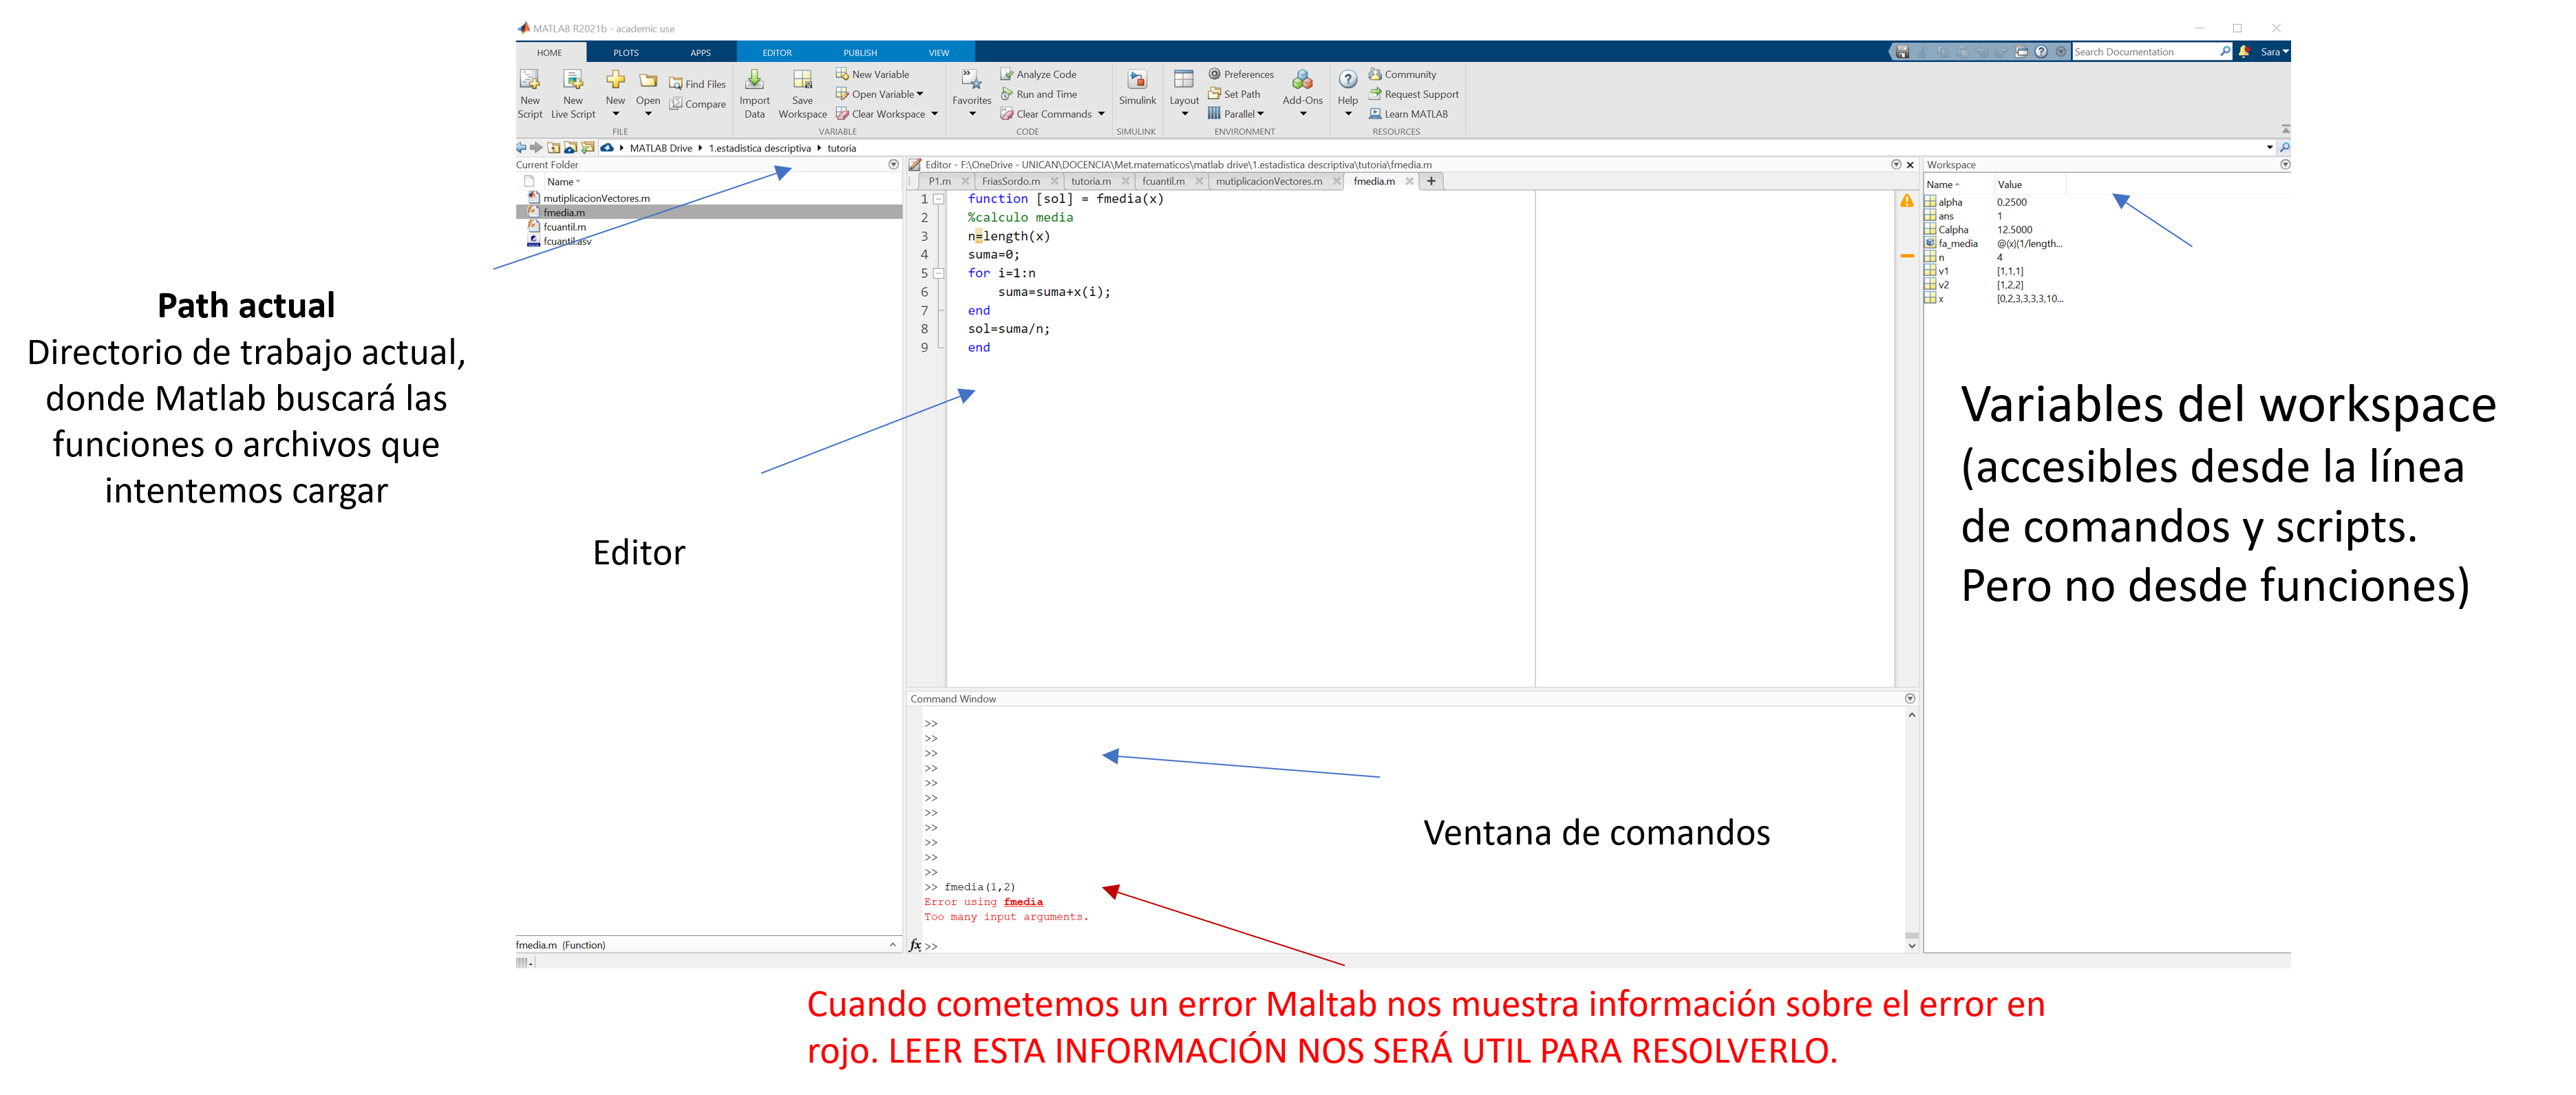

Si al abrir MATLAB no tiene un aspecto similar al de la imagen puede que tengas seleccionado otro layout. Para poner el layout o disposión de los elementos por defecto Seleccion Layout->Default en la pestaña Home.

## **Introducción**

El nombre de MATLAB es un acrónimo de MATrix LABoratory. Hoy en día MATLAB es un programa muy potente con un entorno agradable, que incluye herramientas de visualización gráfica, así como un lenguaje de alto nivel. La interfaz principal de MATLAB se divide en varias partes:

- Las órdenes a ejecutar se escriben en el *Command Window* (ventana de comandos).

- En el editor (ventana *Editor*) es donde escribimos código que guardaremos en scripts (con extensión *.m) *o live scripts (extensión *.mlx*), para su posterior ejecución desde el *Command Window*. El color que aparece en la barra lateral a la derecha del script nos indica si la sintáxis es correcta (verde), es correcta pero podría llegar a dar problemas (naranja) o es incorrecta (rojo). Los comentarios (texto no ejecutable) se introducen con el caracter "*%".*

- La ventana *Workspace *(espacio de trabajo) proporciona información sobre las variables que están almacenadas en memoria.

Hay ciertas reglas para definir variables en MATLAB:

- Su nombre puede tener como máximo 63 caracteres que pueden ser letras, números y el guión bajo.

- El primer carácter tiene que ser una letra: *matriz2* es un nombre válido, *2matriz* no lo es.

- Las mayúsculas y las minúsculas tienen valor distintivo: la variable *X* es distinta de la variable *x*.

- No puede haber espacios en blanco: *modulo1 *es un nombre de variable válido, *modulo 1* no.

- Existen nombres que deben evitarse porque tienen significado propio en MATLAB: *ans*, *pi*, *Inf*, *i*, . . .

A tener en cuenta:

- Si se escribe el caracter "*;"* al final de una linea de código, dicha línea es ejecutada, pero el resultado de la ejecución no se muestra por pantalla.

- Si queremos desasignar (borrar) una variable podemos usar el comando *clear* seguido del nombre de la variable. Para desasignar todas usamos *clear all*

- Los comandos *help, doc y lookfor* sirven para obtener ayuda sobre el resto de comandos/funciones. La documentación online de MATLAB (accesible mediante *doc*) es realmente buena.

help diag
lookfor diagonal

## **Operaciones básicas**

La forma de operar con MATLAB es igual que con una calculadora de bolsillo, usando los símbolos *+, -, *, /, ^*. Por ejemplo:

- Suma y resta:

2+4
2-4

- Multiplicación y división:

2*pi
pi/10

- Potenciación:

3^2

- Otros operadores importantes:

sqrt(4)  % raíz cuadrada
log(1)  % logaritmo neperiano
exp(1)  % exponencial
sin(pi/2)  % seno
cos(pi/2)  % coseno
tan(pi/2)  % tangente

- Formatos:

format short  % o simplemente "format": 4 cifras decimales
1/3
format long  % 15 cifras decimales
1/3
format rat  % formato racional
1/3
format short  % volvemos al formato corto de 4 cifras decimales. Si no añadimos nada después de format, carga el short

## **Creación de vectores y matrices**

Hay varias maneras de crear un vector fila:

a = [1 4 9]
a = [1, 4, 9]  % podemos dejar un espacio en blanco entre números o poner una coma
a = 1:2:10  % secuencia regular de elementos entre 1 y 10, escogidos de 2 en 2

Para crear un vector columna:

b = [-1; 2; 3]
b = [1 2 3]'  % la comilla simple se utiliza para trasponer

Para crear una matriz combinamos la definición de vector fila y vector columna. Por ejemplo:

M = [1 2 3; 4 5 6]  % matriz de 2 filas y 3 columnas
A = [1 2 1; 2 4 3; 3 5 2]  % matriz de 3 filas y 3 columnas

Se pueden seleccionar elementos de una matriz indicando, entre paréntesis, la posición de la fila y la columna.

A(1, 3)  % elemento de la primera fila y tercera columna

Para extraer filas o columnas enteras se utiliza el símbolo "*:"*

A(2, :)  % fila 2
A(:, 1)  % columna 1
A(:, 1:2) % columnas 1, 2 y 3
A(:, [1, 3]) % columnas 1 y 3

Para crear una matriz de ceros:

mceros = zeros(2,3)  % matriz con 2 filas y 3 columnas de ceros

Para crear una matriz de unos:

munos = ones(2,3)  % matriz con 2 filas y 3 columnas de unos

Para crear la matriz identidad:

I5 = eye(5)  % matriz identidad de orden 5

Para crear una matriz de números aleatorios:

maleatoria = rand(3,3)  % matriz 3x3 de números aleatorios (entre el 0 y el 1) 

Para extraer la diagonal principal de una matriz:

d = diag(maleatoria)

Para transponer una matriz:

M'  % transpuesta de M

Para saber cuál es el tamaño de una matriz:

size(M)  % tamaño (filas x columnas) de M

En el caso de un vector, podemos comprobar su longitud con *length*:

v = [5 6 -5 1 0];
length(v)  % número de elementos en un vector fila

Sean $A$ y $B$ dos matrices tales que:

A = [3 -2 1; 4 -8 -1; -5 2 2]
B = [1 -1 0; -2 2 6; 7 -2 -1]

Como ya sabemos $A*B$ no es lo mismo que $B*A$:

A*B  % producto matricial
B*A

## **Cálculo del determinante de una matriz**

det(A)   % determinante de la matriz A

## **Cálculo de la traza de una matriz**

trace(A)

## **Cálculo de la matriz inversa**

Para calcular la matriz inversa se utiliza el comando ***inv***. Antes de calcular la inversa es necesario comprobar si la matriz se puede invertir calculando su determinante.

inv(A)  % inversa de la matriz A

Cuando una matriz es singular (no regular) el resultado de hacer la inversa es el siguiente: 

inv([2 2 ; 4 4])

## Concatenación de matrices

Podemos definir una matriz concatenando dos o más matrices. 

El siguiente ejemplo concatena el vector v=[ 1 2 3] a la derecha de la matriz identidad de orden 3, guardando el resultado en la matriz B. Para poder concatenar a la derecha de la matriz identidad una matriz/vector este deberá tener dimensiones adecuadas (3 filas).

v=[1 2 3]
B=[eye(3) v']%concatenamos un vector columna

Ahora concatenaremos debajo de la matriz B el siguiente vector w=[1 2 3 4]. Para concatenar "debajo" indicaremos con ";" el salto de fila. La matriz resultante la guardaremos en C.

w=[1 2 3 4]%fector fila
C=[B ; w] %concatenamos el vector fila w

## **Precisión en Matlab**

Los cálculos realizados en el ordenador pueden introducir pequeños errores de precisión o redondeo. Estos errores son normales y esperados debido a la representación finita de los números en las computadoras, pero hay que saber interpretarlos. Recuerda, ¡tu ordenador no puede guardar los infinitos decimales del número $\pi$ o de la fracción $\frac{1}{3}$! En tales casos, dos valores que teóricamente deberían ser iguales (como el resultado de una operación matemática y su valor teórico exacto) pueden no serlo estrictamente debido a estos pequeños errores. A continuación, podemos ver el resultado del cálculo de un determinante cuyo valor debería ser 0.

A=[1 2 3; 4 5 6; 7 8 9];
determinante1=det(A)

El valor del número obtenido es $6,661338147750939\cdot \;{10}^{-16}$ 

Otro ejemplo similar:

a = 0.1;
b = 0.2;
c = 0.3;
resultado =c-a-b

## Ejercicios propuestos

**EJERCICIOS PREPARACIÓN PRÁCTICA 1**

**Ejercicio 1: **

Crea las siguientes matrices:

- Matriz $4\times4$ con todos sus elementos cero

- Matriz $4\times4$ con todos sus elementos iguales a $0.5$

- Matriz $3\times5$ con todos sus elementos iguales a $\pi$

**Ejercicio 2:**

Sea la matriz $A=\left\lbrack \begin{array}{cccc}
1 & 3 & 2 & -1\\
0 & 0 & 2 & 5\\
-2 & 0 & 0 & 3\\
1 & 1 & 1 & -1
\end{array}\right\rbrack$

- Calcula la traza y el determinante

- Sustituye el elemento $a_{23}$ por un $-3$ y el $a_{12}$ por un $7$, y llama $$B$$ a la matriz resultante

- Extrae en un vector la primera fila de $$B$$, y en otro vector la segunda columna de $$B$$

- Extrae en una matriz $C$ las filas $1$ y $3$ de $B$ y en otra matriz $D$ las columnas $2$ y $4$

- Añade la matriz identidad $4\times4$ ($$I_{4\times4}$ $) a la derecha de $B$, y llama a la matriz resultante $B^*$. ¿Tienes algún problema?          

- Añade la matriz identidad $4\times4$ ($$I_{4\times4}$ $) debajo de $B$, y dale el nombre que quieras a la matriz resultante

- Crea un vector cuyos elementos sean los términos de la diagonal principal de $A$

- Crea una matriz 4x4 de números aleatorios entre $0$ y $1$ y súmasela a la matriz $A$

**Ejercicio 3:**

Halla la inversa de la matriz $\left\lbrack \begin{array}{cc}
1 & 2\\
4 & 8
\end{array}\right\rbrack$. ¿Qué sucede? ¿Por qué?

**Ejercicio 4:**

Sean las matrices $A=\left\lbrack \begin{array}{ccc}
2 & 1 & 3\\
-2 & -1 & 0\\
-4 & 1 & 1
\end{array}\right\rbrack$y $B=\left\lbrack \begin{array}{ccc}
0 & 1 & -1\\
1 & 2 & -1\\
1 & 0 & 7
\end{array}\right\rbrack$. Halla la matriz $X$ que cumple que $AX=B$.

**Ejercicio 5**:

Halla la matriz $A$ sabiendo que $B^{-1} =\left\lbrack \begin{array}{ccc}
1 & -1 & 2\\
3 & 0 & 1\\
4 & -2 & -2
\end{array}\right\rbrack$y ${\left(\textrm{AB}\right)}^{-1} =\left\lbrack \begin{array}{ccc}
2 & -1 & -5\\
0 & 0 & 1\\
-1 & -3 & 6
\end{array}\right\rbrack$. Comprueba que el resultado que has obtenido es correcto.

**Solución 1:**

Crea las siguientes matrices:

- Matriz $4\times4$ con todos sus elementos cero

zeros(4,4)

- Matriz $4\times4$ con todos sus elementos iguales a $0.5$

zeros(4,4)+0.5  % primera opción
ones(4,4)*0.5  % segunda opción

- Matriz $3\times5$ con todos sus elementos iguales a $\pi$

zeros(3,5)+pi  % primera opción
ones(3,5)*pi  % segunda opción

**Solución 2:**

Sea la matriz $A=\left\lbrack \begin{array}{cccc}
1 & 3 & 2 & -1\\
0 & 0 & 2 & 5\\
-2 & 0 & 0 & 3\\
1 & 1 & 1 & -1
\end{array}\right\rbrack$

- Calcula la traza y el determinante

A = [1 3 2 -1; 0 0 2 5; -2 0 0 3; 1 1 1 -1];   % defino la matriz A
traza = trace(A)
determinante = det(A)

- Sustituye el elemento $a_{23}$ por un $-3$ y el $a_{12}$ por un $7$, y llama $$B$$ a la matriz resultante

B = A; B(2,3) = -3; B(1,2) = 7; 

- Extrae en un vector la primera fila de $$B$$, y en otro vector la segunda columna de $$B$$

B(1, :)  % primera fila de B
B(:, 2)  % segunda columna de B

- Extrae en una matriz $C$ las filas $1$ y $3$ de $B$ y en otra matriz $D$ las columnas $2$ y $4$

C = B([1 3], :)  % filas 1 y 3 de B
D = B(:, [2 4])  % columnas 2 y 4 de B

- Añade la matriz identidad $4\times4$ ($$I_{4\times4}$ $) a la derecha de $B$, y llama a la matriz resultante $B^*$. ¿Tienes algún problema?

BB = [B, eye(4)]  % el nombre de variable B* no esta permitido, llamo a esta nueva matriz BB

- Añade la matriz identidad $4\times4$ ($$I_{4\times4}$ $) debajo de $B$, y dale el nombre que quieras a la matriz resultante

BBB = [B; eye(4)]

- Crea un vector cuyos elementos sean los términos de la diagonal principal de $A$

v = diag(A)

- Crea una matriz $4\times4$ de números aleatorios entre $0$ y $1$ y súmasela a la matriz $A$

A + rand(4,4)

**Solución 3:**

Halla la inversa de la matriz $\left\lbrack \begin{array}{cc}
1 & 2\\
4 & 8
\end{array}\right\rbrack$. ¿Qué sucede? ¿Por qué?

inv([1 2; 4 8])  % el propio MATLAB nos dice que la matriz es singular (no invertible)
det([1 2; 4 8])  % el motivo es que su determinante es 0

**Solución 4:**

Sean las matrices $A=\left\lbrack \begin{array}{ccc}
2 & 1 & 3\\
-2 & -1 & 0\\
-4 & 1 & 1
\end{array}\right\rbrack$y $B=\left\lbrack \begin{array}{ccc}
0 & 1 & -1\\
1 & 2 & -1\\
1 & 0 & 7
\end{array}\right\rbrack$. Halla la matriz $X$ que cumple que $AX=B$.

A = [2 1 3; -2 -1 0; -4 1 1];
B = [0 1 -1; 1 2 -1; 1 0 7];
X = inv(A)*B  % para despejar X, sólo hay que multiplicar por A^-1 a los dos lados 
% de la ecuación que nos da el enunciado

A*X - B  % comprobación

**Solución 5:**

Halla la matriz $A$ sabiendo que $B^{-1} =\left\lbrack \begin{array}{ccc}
1 & -1 & 2\\
3 & 0 & 1\\
4 & -2 & -2
\end{array}\right\rbrack$y ${\left(\textrm{AB}\right)}^{-1} =\left\lbrack \begin{array}{ccc}
2 & -1 & -5\\
0 & 0 & 1\\
-1 & -3 & 6
\end{array}\right\rbrack$. Comprueba que el resultado que has obtenido es correcto.

Binv = [1 -1 2; 3 0 1; 4 -2 -2];  % defino B^(-1)
ABinv = [2 -1 -5; 0 0 1; -1 -3 6];  % defino (AB)^(-1)

A = inv(ABinv)*Binv  % ((AB)^(-1))^(-1) = AB, por tanto AB*B^(-1)=A
% comprobación de que (A*B)^(-1)  produce la matriz del enunciado:
% (A*B)^-1 = B^-1 * A^-1  por tanto,
Binv*inv(A) - ABinv    % tiene que tener todos los elementos cero